# Práctica 9: Eliminación de ruido periódico usando FFT2

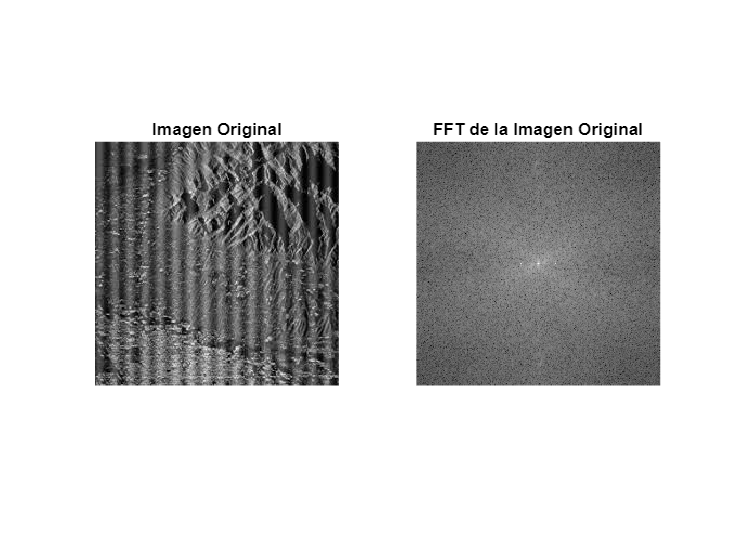

% Cargar imagen
img = imread("ruido_periodico.jpg");
img_gray = rgb2gray(img);

% Aplicar Trans Fourier
f = fft2(img_gray);
f_shifted = fftshift(f);
abs_f_shifted = log(abs(f_shifted) + 1);

figure;
subplot(1,2,1), imshow(img_gray), title('Imagen Original');
subplot(1,2,2), imshow(abs_f_shifted, []), title('FFT de la Imagen Original');

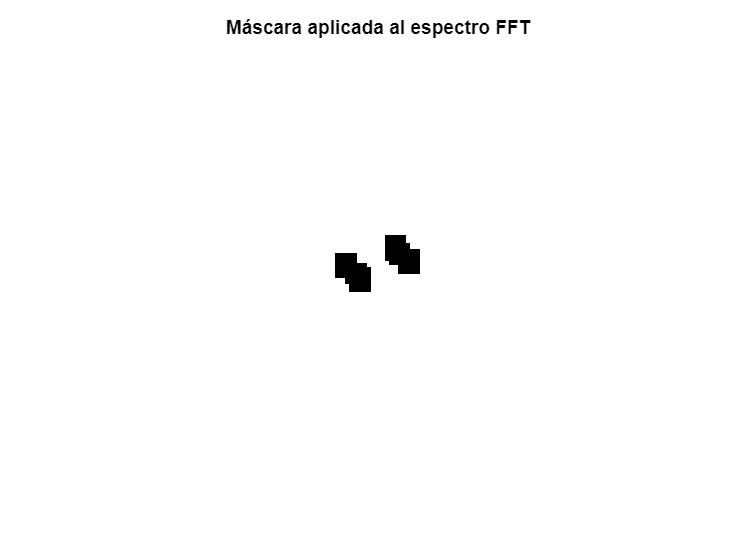


% Definir los parámetros del filtro
[alto, ancho] = size(f_shifted);
cx = round(ancho / 2);
cy = round(alto / 2);

% Umbral para detectar picos en el espectro
umbral = max(abs_f_shifted(:)) * 0.7;
picos = abs_f_shifted > umbral;

% Identificar coordenadas picos
[rows, cols] = find(picos);

% Excluir el centro del espectro
distancias = sqrt((rows - cy).^2 + (cols - cx).^2);
indices_picos = distancias > 10;
picos_relevantes = [rows(indices_picos), cols(indices_picos)];

%Filtro ruido periódico
filtro_ruido = ones(alto, ancho);
ancho_pico = 5;
for k = 1:size(picos_relevantes, 1)
    x_pico = picos_relevantes(k, 2);
    y_pico = picos_relevantes(k, 1);
    for i = -ancho_pico:ancho_pico
        for j = -ancho_pico:ancho_pico
            if (y_pico + i > 0 && y_pico + i <= alto && x_pico + j > 0 && x_pico + j <= ancho)
                filtro_ruido(y_pico + i, x_pico + j) = 0;
            end
        end
    end
end

% Aplicar filtro a fft
f_filtrado = f_shifted .* filtro_ruido;

% Trans inversa para obtener la imagen filtrada
img_filtrada = ifft2(ifftshift(f_filtrado));
img_filtrada = abs(img_filtrada);

% Trans Fourier Img Filtrada
f_shifted_filtro = fftshift(fft2(img_filtrada));
abs_f_shifted_filtro = log(abs(f_shifted_filtro)+1);

figure;
imshow(filtro_ruido, []), title('Máscara aplicada al espectro FFT');

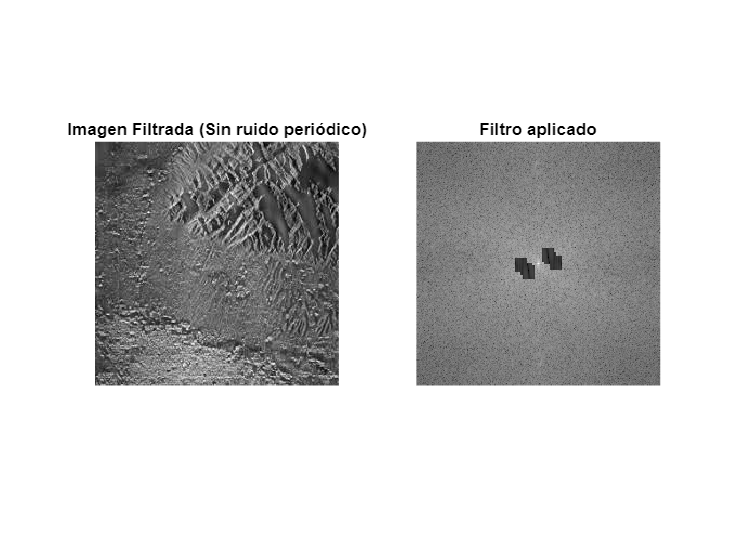


figure;
subplot(1,2,1), imshow(img_filtrada, []), title('Imagen Filtrada (Sin ruido periódico)');
subplot(1,2,2), imshow(abs_f_shifted_filtro, []), title('Filtro aplicado');